# **MEC4127F: Introduction to Robotics**

# Chapter 4: Pose estimation

## 4.1 Introduction

...

Inertial navigation systems

## 4.2 Inertial measurement units

Modern micro-electromechanical systems (MEMs) IMUs are popular choices for use in robotics based on their exceedingly low price point and footprint. 

...

Inertial measurement units (IMUs) have the same general structure of


$${\bf x}^\#={\bf S}{\bf x}+{\bf b}+{\bf n},$$


where ${\bf x}$ is the true signal, ${\bf x}^\#$ is the measurement from the sensor, $\bf S$ is an unknown scale factor, $\bf b$ is a time-varying bias, and $\bf n$ is random, zero-mean noise. Modern sensors are usually sold with ${\bf S}\approx {\bf I}$, with some quoted tolerance in the datasheet. We will assume in this course that ${\bf S}={\bf I}$ to keep things a bit simpler. Bias term ${\bf b}$ is often temperature dependant and can either be precompensated for if a temperature measurement is available on the IMU, or estimated in real-time, as we will shown in a latter section. Noise term $\bf n$ is non-deterministic, meaning that we cannot ever measure it in any useful way. However, we will show in this Chapter how sensor fusion (combining measurements from multiple sensors) can be used to circumvent problematic noise levels.

### 4.2.1 Gyroscopes

Any sensor that measures the rate of change of orientation is known as a gyroscope. The gyroscope found in an IMU provides a convenient measure of rotational velocity. If the sensor is correctly calibrated, the measurement is very reliable and can often be provided at high sampling rates of over $1$kHz. As we will show in the following subsections, gyroscopes struggle when estimating orientation over time due to an effect known as drift.

#### 4.2.1.1 Measurement equation

Assuming the IMU frame is aligned with $\{B\}$, the generalised measurement equation of a gyroscope is given by


$${^B{\bf \omega}^\#}={^B{\bf \omega}}+{\bf b}_\omega+{\bf n}_\omega,$$


where ${^B{\bf \omega}}$ is the true angular velocity experienced by the sensor (and by extension, frame $\{B\}$, ${^B{\bf \omega}^\#}$ is the measured signal, with the superscript $\#$ indicating a measured quantity, ${{\bf b}_\omega}$ is an unknown and time-varying bias term, and ${{\bf n}_\omega}$ is nondeterministic measurement noise, which is often treated as white noise.

#### 4.2.1.2 Bias compensation

The unknown bias term of ${{\bf b}_\omega}$ needs to be accounted for when estimating angular velocity. Angular velocity bias is temperature dependant and has an approxiately linear relationship with incremental changes in temperature. For this reason, most MEMS IMUs also include temperature sensing modules to actively account for this. The bias term can be approximately inferred from IMU temperature based on


$${\overline{\bf b}_\omega} =  {{\bf b}_\omega}(0)+{\bf C} \Delta T^\#,$$


where ${\overline{\bf b}_\omega} $ is the estimated bias term, with the overbar of $\overline$ indicating the parameter is an estimate, ${{\bf b}_\omega}(0)$ is the initial bias term at time $t=0$, ${\bf C}$ is a diagonal matrix of gradient coefficients, and $\Delta T^\#$ is the measured differential temperature on the IMU.

If the IMU is constrained such that angular velocity is not experienced, then the measurement equation becomes


$$\begin{array}{ll}
{^B{\bf \omega}^\#}
&={\bf b}_\omega+{\bf n}_\omega,\\
&\approx {{\bf b}_\omega}(0)+{\bf C} \Delta T^\#+{\bf n}_\omega.
\end{array}$$


In this configuration, as the gyroscope experiences an increase of temperate, a corresponding straight line response will be seen on each channel of the gyroscope, with the respective y-intercepts corresponding to ${{\bf b}_\omega}(0)$, and the gradients corresponding to the diagonal elements of $\bf C$. One can therefore de-bias the gyroscope reading using ${{\bf b}_\omega^\hat}$ if the sensor has been calibrated, which yields an estimate for the angular velocity, namely


$$\begin{array}{ll}
{^B\overline{\bf \omega}}
&={^B{\bf \omega}^\#}-{\overline{\bf b}_\omega},\\
&={^B{\bf \omega}}+\left({\bf b}_\omega-{{\overline{\bf b}_\omega}}\right)+{\bf n}_\omega, \\
&\approx{^B{\bf \omega}}+{\bf n}_\omega.
\end{array}$$


#### Example: Calibrating a gyroscope

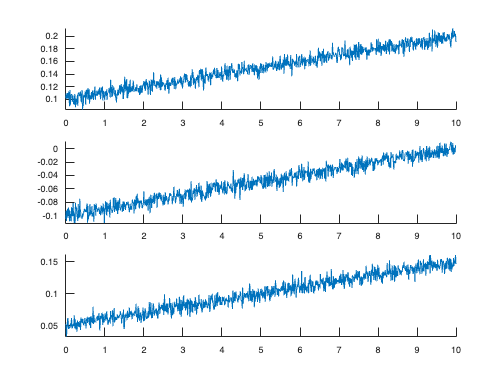

IMU = imuSensor;
IMU.Gyroscope.NoiseDensity = 1e-3;
IMU.Gyroscope.ConstantBias = [0.1 -0.1 0.05];
IMU.Gyroscope.TemperatureBias = 1e-3*ones(1,3);
IMU.Temperature = 25;

dT = 0.01;
numSamples = 1000;
t = (0:numSamples-1)*dT;

omega = zeros(1,3);
omege_meas = zeros(numSamples,3);
temp = zeros(numSamples,1);

for k=1:numSamples
    [~,omega_meas(k,:)] = IMU(zeros(1,3),omega);
    temp(k) = IMU.Temperature;
    IMU.Temperature = IMU.Temperature+0.1;
   

end

% b = IMU.Gyroscope.ConstantBias + (temp-25) * IMU.Gyroscope.TemperatureBias(1);

figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1))
subplot(3,1,2),hold on
plot(t,omega_meas(:,2))
subplot(3,1,3),hold on
plot(t,omega_meas(:,3))

We can fit a straight line to this data using MATLAB (or roughly by hand), which gives the following behaviour.

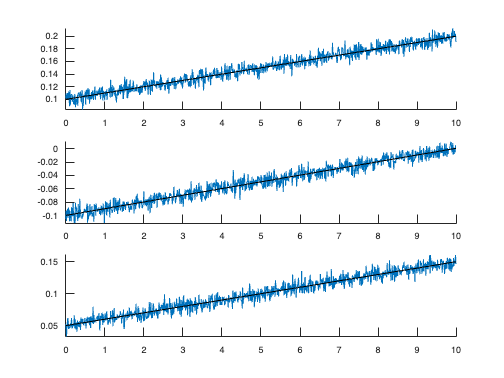

p1 = polyfit(temp-temp(1),omega_meas(:,1),1);
p2 = polyfit(temp-temp(1),omega_meas(:,2),1);
p3 = polyfit(temp-temp(1),omega_meas(:,3),1);

b = zeros(numSamples,3);
b(:,1) = p1(2)+p1(1)*(temp-temp(1));
b(:,2) = p2(2)+p2(1)*(temp-temp(1));
b(:,3) = p3(2)+p3(1)*(temp-temp(1));

figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1))
plot(t,b(:,1),'k')
subplot(3,1,2),hold on
plot(t,omega_meas(:,2))
plot(t,b(:,2),'k')
subplot(3,1,3),hold on
plot(t,omega_meas(:,3))
plot(t,b(:,3),'k')

Using $\begin{array}{ll}
{^B\overline{\bf \omega}}
&={^B{\bf \omega}^\#}-{\overline{\bf b}_\omega}
\end{array}$, we can plot the resulting estimated angular velocity, which we know should be equal to zero.

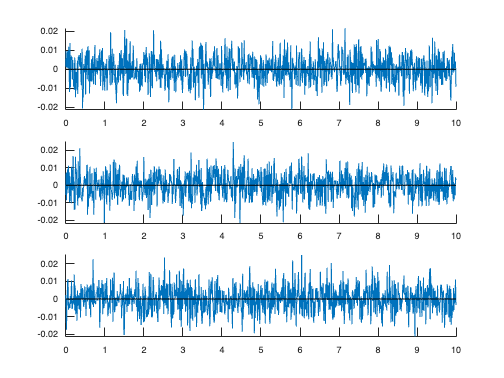

figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1)-b(:,1))
line(xlim, [0,0], 'Color', 'k', 'LineWidth', 1); % Draw line for X axis.
subplot(3,1,2),hold on
plot(t,omega_meas(:,2)-b(:,2))
line(xlim, [0,0], 'Color', 'k', 'LineWidth', 1); % Draw line for X axis.
subplot(3,1,3),hold on
plot(t,omega_meas(:,3)-b(:,3))
line(xlim, [0,0], 'Color', 'k', 'LineWidth', 1); % Draw line for X axis.

#### 4.2.1.3 Estimating orientation using rotation matrices

Recall from Chapter 3 that if the angular velocity is exactly known for a period of $\Delta t$ units of time, then the incremental exponential coordinates are given by


$${^B\Delta{\bf \theta}={^B{\bf \omega}}\Delta t.$$


The incremental axis-angle form was given by


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$
           
$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|},$$


and the corresponding incremental rotation matrix was


$$\begin{array}{ll}
\Delta{\bf R}
&=\mathrm{e}^{\lfloor {^B{\Delta\bf \theta}} \rfloor},\\
&=\mathrm{e}^{\lfloor {^B{\bf \omega}}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos\Delta\alpha\right)\lfloor ^B\hat{\bf \omega} \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}}|\Delta t)\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos(|{^B{\bf \omega}}|\Delta t)\right)\lfloor ^B\hat{\bf \omega} \rfloor^2.
\end{array}
$$


Assuming that the angular velocity measurement has been sufficiently de-biased, one can similarly integrate ${^B\overline{\bf \omega}}$ to obtain an orientation *estimate*. Replacing ${^B{\bf\omega}}$ with ${^B\overline{\bf\omega}}$ for the above equations yields


$${^B\Delta\overline{\bf \theta}={^B\overline{\bf \omega}}\Delta t,$$
     
$$\Delta \overline\alpha=|{^B\overline{\bf \omega}}|\Delta t,$$
      
$${^B\overline\hat{\bf \omega}}=\frac{^B\overline{\bf \omega}}{|{^B\overline{\bf \omega}}|},$$


and 


$$\begin{array}{ll}
\Delta\overline{\bf R}
&=\mathrm{e}^{\lfloor {^B{\Delta\overline{\bf \theta}}} \rfloor},\\
&=\mathrm{e}^{\lfloor {^B\overline{\bf \omega}}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\overline\alpha\lfloor ^B\overline\hat{\bf \omega} \rfloor +\left(1-\cos\Delta\overline\alpha\right)\lfloor ^B\overline\hat{\bf \omega} \rfloor^2,\\
&={\bf I}+\sin(|{^B\overline{\bf \omega}}|\Delta t)\lfloor ^B\overline\hat{\bf \omega} \rfloor +\left(1-\cos(|{^B\overline{\bf \omega}}|\Delta t)\right)\lfloor ^B\overline\hat{\bf \omega} \rfloor^2.
\end{array}
$$


An estimated angular velocity experienced by a rigid body that moves it from frame $\{0\}$ to $\{1\}$ over a period of $\Delta t$ units is then described by


$${^W\overline{\bf R}_{\{1\}}}={^W\overline{\bf R}_{\{0\}}}{^{\{0\}}\overline{\bf R}_{\{1\}},$$
 

where $\Delta\overline{\bf R}={^{\{0\}}\overline{\bf R}_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. 

In practice, angular velocity measurements will be obtained from a gyroscope at discrete intervals, as opposed to being a continuous signal. If we make the assumption that the angular velocity is constant during each sampling instance of length $\Delta t$, then we define our incremental rotation at sample time $k$ as 


$$\begin{array}{ll}
\Delta\overline{\bf R}_k
&={^{\{k-1\}}{\bf R}_{\{k\}},\\
&=\mathrm{e}^{\lfloor {^B\overline{\bf \omega}_k}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\overline\alpha_k\lfloor ^B\overline\hat{\bf \omega}_k \rfloor +\left(1-\cos\Delta\overline\alpha_k\right)\lfloor ^B\overline\hat{\bf \omega}_k \rfloor^2,\\
&={\bf I}+\sin(|{^B\overline{\bf \omega}_k}|\Delta t)\lfloor ^B\overline\hat{\bf \omega}_k \rfloor +\left(1-\cos(|{^B\overline{\bf \omega}_k}|\Delta t)\right)\lfloor ^B\overline\hat{\bf \omega}_k \rfloor^2.
\end{array}
$$


The estimated orientation at sample instance $k$ follows as


$$\begin{array}{ll}
{^W\overline{\bf R}_{\{k\}}}
&={^W\overline{\bf R}_{\{0\}}}{^{\{0\}}\overline{\bf R}_{\{1\}} \dots {^{\{k-1\}}\overline{\bf R}_{\{k\}},\\
&={^{W}\overline{\bf R}_{\{k-1\}} {^{\{k-1\}}\overline{\bf R}_{\{k\}},\\
\end{array}$$
 

where each rotation matrix estimate is obtained from a particular sampling instance, after integrating the angular velocity and applying the exponential coordinate mapping. 

The angular velocity estimate ${^B\overline{\bf \omega}}$ is notably imperfect, as a result of sensor resolution, noise term ${\bf n}_\omega$, as well as the potential biasing as a result of ${{\overline{\bf b}_\omega}}\neq{\bf b}_\omega$. Additionally, the assumption that the estimated angular velocity is constant for the full duration of the sampling period will also result in an imperfect estimate of the incremental exponential coordinates, based on ${^B\Delta\overline{\bf \theta}={^B\overline{\bf \omega}}\Delta t$. For this reason, the orientation estimate using the approach outline above will ultimately experience drift (or random walk) that cannot be compensated for. The result is that the orientation estimate will become poorer over time, as the errors from the imperfect angular velocity estimate and sampling assumptions accumulate. This problem can be solved using sensor fusion, which is introduced in Section 4.3.

#### 4.2.1.4 Estimation orientation using quaternions

As shown in Chapter 3, The quaternion is an alternative approach to determining orientation from angular velocity information. Given an angular velocity estimate of ${^B\overline{\bf \omega}}_k$ at sample instance $k$, the angle-axis representation of the incremental rotation can be determined by


$$\Delta \overline\alpha_k=|{^B\overline{\bf \omega}_k}|\Delta t,$$
      
$${^B\overline\hat{\bf \omega}_k}=\frac{^B\overline{\bf \omega}_k}{|{^B\overline{\bf \omega}_k}|},$$


which is equivalent to the axis-angle representation of the incremental exponential coordinates in the previous subsection. The incremental quaternion at sample instance $k$ follows as


$$\begin{array}{cc}\Delta\overline{\mathbf q}_k =
{^{\{k-1\}}\overline{\bf q}_{\{k\}}
= \left[\begin{array}{cc}    \cos{\frac{\Delta\overline\alpha_k}{2}} \\ \sin{\frac{\Delta\overline\alpha_k}{2}} {^B\overline\hat{\mathbf \omega}_k}     \\ \end{array}\right],\end{array}$$


with the absolute estimated quaternion given by


$$\begin{array}{ll}
{^W\overline{\bf q}_{\{k\}}}
&={^W\overline{\bf q}_{\{0\}}}\otimes{^{\{0\}}\overline{\bf q}_{\{1\}}\otimes \dots \otimes{^{\{k-1\}}\overline{\bf q}_{\{k\}}, \\
&={^W\overline{\bf q}_{\{k-1\}}} \otimes{^{\{k-1\}}\overline{\bf q}_{\{k\}}.
\end{array}$$
 

As with the rotation matrix approach, estimating the quaternion orientation using only estimated (and imperfect) angular velocity information will result in orientation errors over time.

#### Example: Estimating orientation from a gyroscope

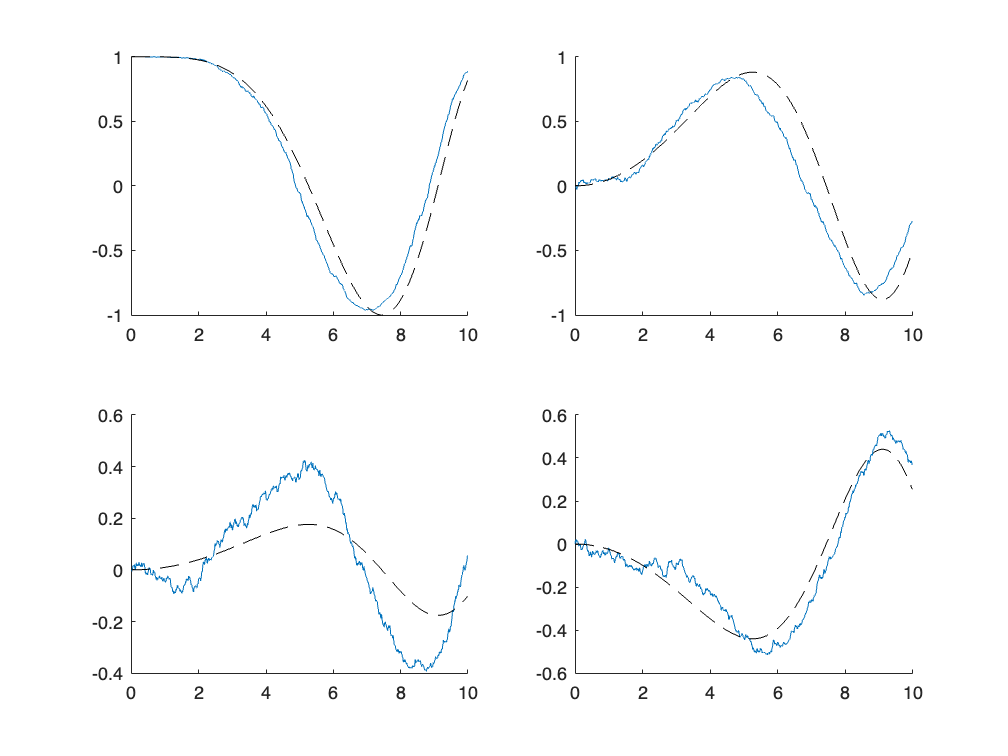

IMU = imuSensor;
IMU.Gyroscope.NoiseDensity = 0.09701;
% IMU.Gyroscope
dT = 0.01;
numSamples = 1000;
t = (0:numSamples-1)*dT;

omega1 = linspace(0,1,numSamples);
omega2 = linspace(0,0.2,numSamples);
omega3 = linspace(0,-0.5,numSamples);
omega = [omega1' omega2' omega3'];


q_ = zeros(numSamples,4);
q_(1,1:4) = [1 0 0 0];
q = q_;

for k=1:numSamples-1
    %actual
    dtheta = omega(k,:)*dT;
    dalpha = norm(dtheta);
    if( dalpha == 0)
        v = [0 0 0];
    else
        v = dtheta/dalpha;
    end
    dq = [cos(dalpha) sin(dalpha)*v];
    q(k+1,1:4) = quatmultiply(q(k,1:4),dq);
    q(k+1,1:4) = q(k+1,1:4)/norm( q(k+1,1:4) );


    %estimate
    [~,omega_meas] = IMU(zeros(1,3),omega(k,:));
    dtheta_ = omega_meas*dT;
    dalpha_ = norm(dtheta_);
    if( dalpha_ == 0 )
        v_ = [0 0 0];
    else
        v_ = dtheta_/dalpha_;
    end
    dq_ = [cos(dalpha_) sin(dalpha_)*v_];
    q_(k+1,1:4) = quatmultiply(q_(k,1:4),dq_);
    q_(k+1,1:4) = q_(k+1,1:4)/norm( q_(k+1,1:4) );
end
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k')

### 4.2.2 Accelerometers

Accelerometers are sensors that measure acceleration, albeit indirectly. Even when not moving they sense the acceleration due to gravity which defines the direction we know as downward. Gravitational acceleration is a function of the material in the Earth beneath us and our distance from the Earth’s center. 

As we will show in the following subsections, we can either use an accelerometer to (partiall) estimate orientation when there is no translational acceleration, or estimate acceleration when the orientation is sufficiently well known. We cannot simultaneously estimate both since there are more unknowns than measurements.

#### 4.2.2.1 Measurement equation

The generalised measurement equation of an accelerometer is given by


$${^B{\bf a}^\#}={^B{\bf a}}+{^B{\bf g}}+{\bf b}_a+{\bf n}_a,$$


where ${^B{\bf a}}$ is the true translational acceleration experienced by the sensor (and by extension, the frame $\{B\}$ centre of mass), $^B{\bf g}$ is the gravitational acceleration vector in $\{B\}$, ${{\bf b}_a}$ is an unknown and possibly time-varying bias term, and ${{\bf n}_a}$ is nondeterministic measurement noise, which is often treated as white noise.

We also know that the gravitational acceleration in $\{W\}$ is given by $^W{\bf g}=[0~0~g]^T$, with $g\approx 9.8$m/s$^2$ (in Cape Town, South Africa). The relationship between the gravitational acceleration in the two frames is simply


$${^B{\bf g}}= {^B{\bf R}_W}{^W{\bf g}},$$


which means that we require knowledge of the orientation when relating the two vectors.

#### 4.2.2.2 Bias compensation

Accelerometers often have constant and slowly time-varying biases that are fairly insensitive to temperate changes. As such, it is often sufficient to just determine the constant bias offset instead if the sensor will be used for short periods of time. In the absence of translational acceleration, the accelerometer equation is given by


$${^B{\bf a}^\#}={^B{\bf g}}+{\bf b}_a+{\bf n}_a.$$


The approximately constant bias terms can then be estimated based on


$$\begin{array}{ll}
\overline{\bf b}_a
&\approx {^B{\bf a}^\#}-{^B{\bf g}},\\
&\approx {^B{\bf a}^\#}-{^W{\bf R}_B}{^W{\bf g}},
\end{array}$$


if the orientation is known sufficiently accurately, for example from a gimballed rig that can measure orientation using encoders/potentiometers. Other calibration procedures exist that do not require knowledge of the orientation, but this will not be explored in this course. Notably, if the above approach is not sufficient for long-term operation of the robot, the process outlined in Section 4.2.1.2 can be retailored for use with an accelerometer.

#### 4.2.2.3 Estimating orientation

Orientation can be partially estimated using an accelerometer if translational acceleration is negligible. Recall that the acceleration model with ${^B{\bf a}}=0$ and $\overline{\bf b}_a={\bf b}_a$ is given by


$$\begin{array}{ll}
{^B{\bf a}^\#}
&={^B{\bf g}}+{\bf n}_a,\\
&={^B{\bf R}_W}{^W{\bf g}}+{\bf n}_a.\\
\end{array}$$


Using the Euler angle parameterisation for the rotation matrix from Chapter 3, namely


$$\begin{array}{cc}^W{\mathbf R}_B =    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right] ,\end{array}$$


and noting that $^W{\bf g}=[0~0~g]^T$, the acceleroment measurement reduces to


$$\begin{array}{ll}
{^B{\bf a}^\#}
&\approx {^B{\bf R}_W}{^W{\bf g}},\\
&\approx g \left[\begin{array}{cc}    -\sin\theta \\ \cos\theta\sin\phi \\ \cos\theta\cos\phi     \\ \end{array}\right].\\

\end{array}$$


Note that the measurement becomes an estimate of the gravity vector in $\{B\}$, based on ${^B{\bf g}}={^B{\bf R}_W}{^W{\bf g}}$. The roll and pitch angles can then be recovered, given that ${^B{\bf a}^\#}$ is obtained as a measurement and $g\approx 9.8$ is known. Notably, the yaw angle, $\psi$ cannot be recovered. This is because the world-frame gravitational vector is always parallel to the $z$-axis of $\{W\}$, meaning that rotations about this axis do not affect the vector.

#### Example: Estimating roll and pitch from an accelerometer

Currently broken!

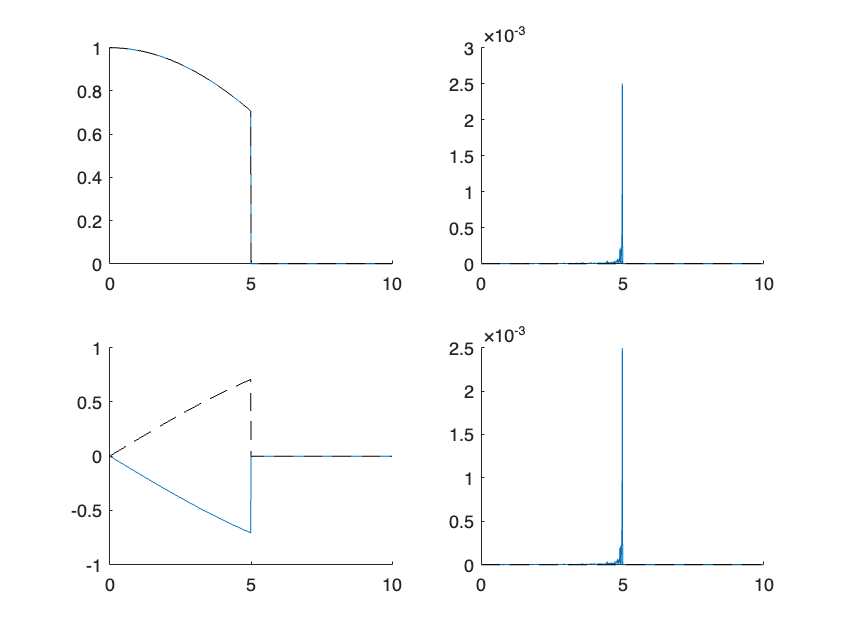

IMU = imuSensor;
IMU.Accelerometer.NoiseDensity = 0.00001;
% IMU.Gyroscope
dT = 0.01;
numSamples = 1000;
t = (0:numSamples-1)*dT;

v = [0 1 0];
alpha = linspace(0,pi,numSamples);
q = zeros(numSamples,4);
q(1,1:4) = [1 0 0 0];

q_ = zeros(numSamples,4);
q_(1,1:4) = [1 0 0 0];
q = q_;

g = 9.8;

for k=1:numSamples/2-1
    q(k+1,:) = [cos(alpha(k+1)/2) sin(alpha(k+1)/2)*v];

    R = quat2rotm(q(k+1,1:4));
    %estimate
    [accel_meas,~] = IMU(zeros(1,3),zeros(1,3),R);
    accel_meas = accel_meas/norm(accel_meas);
    theta = -asin( accel_meas(1) );
    phi = acos( accel_meas(3)/cos(theta) );
    % phi = asin( accel_meas(2)/cos(theta) );

    q_(k+1,1:4) = eul2quat([0,theta,phi],'ZYX');
    % q_(k+1,1:4) = q_(k+1,1:4)/norm( q_(k+1,1:4) );
end
figure
subplot(2,2,1),hold on
plot(t,q_(:,1)),plot(t,q(:,1),'--k')
subplot(2,2,2),hold on
plot(t,q_(:,2)),plot(t,q(:,2),'--k')
subplot(2,2,3),hold on
plot(t,q_(:,3)),plot(t,q(:,3),'--k')
subplot(2,2,4),hold on
plot(t,q_(:,4)),plot(t,q(:,4),'--k')

#### 4.2.2.3 Estimating translational motion

Assuming the orientation of the robot is known, we can separate out the acceleration from the accelerometer measurement. Given the de-biased measurement equation of


$${^B{\bf a}^\#}={^B{\bf a}}+{^B{\bf R}_W}{^W{\bf g}}+{\bf n}_a,$$


and known rotation matrix ${^B{\bf R}_W}$, we can estimate the translational acceleration using


$${^B\overline{\bf a}}\approx{^B{\bf a}^\#}-{^B{\bf R}_W}{^W{\bf g}}.$$


The estimate of the corresponding world-frame acceleration follows as


$$\begin{array}{ll}
{^W\overline{\bf a}}
&={^W{\bf R}_B}{^B\overline{\bf a}},\\
&\approx {^W{\bf R}_B}\left({^B{\bf a}^\#}-{^B{\bf R}_W}{^W{\bf g}}\right),\\
&\approx {^W{\bf R}_B}{^B{\bf a}^\#}-{^W{\bf g}}.
\end{array}$$


We can then integrate this result to obtain the velocity and position estimates, namely


$${^W\overline{\bf v}}(t)=\int_0^t {^W\overline{\bf a}}(t)dt,$$


and


$${^W\overline{\bf p}}(t)=\int_0^t {^W\overline{\bf v}}(t)dt.$$


As with the orientation estimation using a gyroscope, the velocity and position estimates derived from the accelerometer will experience drift. In fact, the double integration of the estimate from acceleration to position means that the error accumulates a lot faster.

#### Example: Estimating position and velocity from an accelerometer

...

### 4.2.3 Magnetometers

The key element of most modern magnetometers is a Hall-effect sensor, a semiconductor device which produces a voltage proportional to the magnetic field intensity in a direction normal to the current flow. Typically three Hall-effect sensors are packaged together and arranged so that their sensitive axes are orthogonal. The three outputs of such a triaxial magnetometer are the components of the Earth’s magnetic field intensity vector measured in $\{B\}$.

Magnetometers are conceptually similar to accelerometers in that one can determine the rotation required to align a body-frame measurement of magenetic north to the world-frame counterpart. However, unlike an accelerometer, magnetometers do not measure translational accelerations. The downside of magnetometers is that they are sensitive to electromagnetic interference, which is a natural by-product of electric motors, among other electronic devices.

#### 4.2.3.1 Measurement equation

Assuming the world-frame $x$-axis points in the direction of magnetic north, the magnetic intensity vector in $\{W\}$ is given by


$${^W{\bf m}}= B\left[\begin{array}{cc}    \cos I \\ 0 \\ \sin I     \\ \end{array}\right],$$


where $B$ is the magnetic field intensity and $I$is the inclination angle. Assuming $I=0$ to keep things simple, the equation above reduces to


$${^W{\bf m}}= B\left[\begin{array}{cc}    1 \\ 0 \\ 0     \\ \end{array}\right].$$


The measurement equation of a magnetometer is given by


$${^B{\bf m}^\#}={^B{\bf m}}+{\bf b}_m+{\bf n}_m.$$


As with the accelerometer, the magnetometer bias term varies slowly over time and can usually be determined approximately as a constant during a calibration process. Assuming this is performed, the resulting measurement equation becomes


$${^B{\bf m}^\#}={^B{\bf m}}+{\bf n}_m.$$


#### 4.2.3.2 Estimating orientation

Orientation can be partially estimated using a magnetometer. Referring to the equation above, the measurement equation can be expressed as


$$\begin{array}{ll}
{^B{\bf m}^\#}
&={^B{\bf m}}+{\bf n}_m,\\
&={^B{\bf R}_W}{^W{\bf m}}+{\bf n}_m,\\
\end{array}$$


which takes a similar form to the accelerometer measurement model when there is no translational motion. It is common to normalise both the known magnetic intensity vector and magnetometer measurement, in order to remove the dependance on $B$:


$$\begin{array}{ll}
{^B\hat{\bf m}^\#}
&={^B\hat{\bf m}}+{\bf n}_m,\\
&={^B{\bf R}_W}{^W\hat{\bf m}}+{\bf n}_m,\\
\end{array}$$


Using the Euler angle parameterisation for the rotation matrix from Chapter 3, namely


$$\begin{array}{cc}^W{\mathbf R}_B =    \left[\begin{array}{cccccccc}    \cos{\psi}\cos{\theta} & \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} & \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}\\    \cos{\theta}\sin{\psi} & \cos{\psi}\cos{\phi}+\sin{\psi}\sin{\theta}\sin{\phi} & \cos{\phi}\sin{\psi}\sin{\theta}-\cos{\psi}\sin{\phi} \\    -\sin{\theta} & \cos{\theta}\sin{\phi} & \cos{\phi}\cos{\theta}    \\ \end{array}\right] ,\end{array}$$


and noting that $^W\hat{\bf m}=[1~0~0]^T$, the magnetometer measurement reduces to


$$\begin{array}{ll}
{^B\hat{\bf m}^\#}
&\approx {^B{\bf R}_W}{^W\hat{\bf m}},\\
&\approx \left[\begin{array}{cc}    \cos{\psi}\cos{\theta} \\ \cos{\psi}\sin{\theta}\sin{\phi}-\cos{\phi}\sin{\psi} \\ \sin{\psi}\sin{\phi}+\cos{\psi}\cos{\phi}\sin{\theta}    \\ \end{array}\right].\\

\end{array}$$


The roll and pitch angles can then be recovered, given that ${^B{\bf a}^\#}$ is obtained as a measurement and $g\approx 9.8$ is known. Notably, the yaw angle, $\psi$ cannot be recovered. This is because the world-frame gravitational vector is always parallel to the $z$-axis of $\{W\}$, meaning that rotations about this axis do not affect the vector.

**NEED TO FIX THIS. USE XYZ Euler?**

### 4.2.4 Normalisation

The process of estimating orientation using rotation matrices or quaternions requires iterative multiplication of matrices or vectors. Given that the hardware (e.g microcontroller or computer) used to make these computations has finite precision, subsequent multiplication operations, followed by numerical truncation, will eventually result in rotation matrices not being orthogonal, or quaternions not being unitary (have unit length). To compensate for this, we can perform a normalisation step at regular intervals, such as after every few samples (the frequency would depend on the numerical precision of the hardware).

#### **4.2.4.1 Rotation matrices**

The basic concept is to enforce each column of the matrix to be orthogonal to the other columns, with unit magnitudes (to preserve the orthogonal property of a rotation matrix). This is done by first selecting one column of  


$${{\mathbf R}}=[{\mathbf c}_1  ~{\mathbf c}_2 ~ {\mathbf c}_3]$$


such as column three, ${\mathbf c}_3$, and assume that the direction is correct, namely


$$\begin{array}{cc}    {\mathbf c}^{'}_3={\mathbf c}_3.\\ \end{array}$$


The (updated) first column, ${\bf c}_1^{'}$, is then set to be orthogonal to the last two columns


$$\begin{array}{cc}    {\mathbf c}^{'}_1={\mathbf c}_2 \times {\mathbf c}^{'}_3.\\ \end{array}$$


Given that the last two columns may not have been orthogonal, we define the second column to be orthogonal to the first and third column


$$\begin{array}{cc}    {\mathbf c}^{'}_2={\mathbf c}^{'}_3 \times {\mathbf c}^{'}_1.\\ \end{array}$$


Finally, each column is individually normalised, in order to preserve unit length


$$\begin{array}{cc}    {\mathbf c}^{'}_i=\frac{ {\mathbf c}^{'}_i }{|{\mathbf c}^{'}_i|},  \forall i\in [1,3].\\ \end{array}$$


The resulting normalised rotation matrix follows as  


$${{\mathbf R}^{'}}=[{\mathbf c}^{'}_1 ~ {\mathbf c}^{'}_2 ~ {\mathbf c}^{'}_3],$$


which now adheres to the othogonality requirements of SO(3).

#### **4.2.4.2 Quaternions**

As with the rotation matrix update, we require normalisation of the quaternion in order to maintain the unitary structure. In the case of the quaternion, normalisation simply requires dividing all elements by the quaternion norm


$$\begin{array}{cc}{{\mathbf q}} = \frac{{{\mathbf q}}}{|{{\mathbf q}}|}, \end{array}$$


which is also computationally efficient.

## 4.3 Explicit complementary filer

The previous section has shown that simply using a gyroscope, accelerometer, or magnetometer on its own is not sufficient to fully and reliably estimate orientation. Sensor fusion is a process of making use of multiple measurements in a strategic way, such that the appealing qualities of each measurement is used and the unappealing qualities discarded, or compensated for by the other sensor measurements. While there are many types of sensor fusion algorithms, we will consider one fairly simple but powerful approach — the explicit complementary filter.

### 4.3.1 Complementary filter

Before diving into the full explicit complementary filter, it is useful to first step back and understand the principle of the complementary filter. Given any arbitrary signal, one can recover the signal after passing it through a low-pass and high-pass filter with matching order and cutoff frequency. By example, it is easy to show that input signal $U(s)$ when passed through a first-order low-pass filter and high-pass filter with cutoff frequency of $a$ rad/s, followed by summing, yields the original signal:


$$\begin{array}{ll}
Y(s)
&=\frac{1}{1+s/a}U(s)+\frac{s/a}{1+s/a}U(s),\\
&=\left(\frac{1}{1+s/a}+\frac{s/a}{1+s/a}\right)U(s),\\
&=\frac{1+s/a}{1+s/a}U(s),\\
&= U(s).
\end{array}$$


We can exploit the complementary relationship to determine an esimate that is derived from filtering two different sensor measurements using a low-pass and high-pass filter. The reasoning for this is that sensors often have appealing characteristics in a particular frequency range but undesirable characteristics in other ranges. In this case, we can try and filter measurements so that only the best qualities of a measurement are retained. 

Consider an IMU that is constrained such that it can only roll about $\hat{\bf x}_W$. In this case, we can obtain an estimate of the orientation from the gyroscope (after integration), and an estimate of the orientation from the accelerometer. As shown previously, the orientation estimate from the gyroscope works well initially but has the problem of drifting over time. As such, it has good high-frequency characteristics but poor low-frequency characteristics. The orientation estimate from the accelerometer contains a lot of high-frequency noise due to the nature of the sensor, but at low frequencies it behaves reliably. These two sensors therefore have good complementary properties and we can use them in a complementary filter to extract their usable frequency ranges.

If the orientation estimate from the gyroscope and accelerometer are expressed in the Laplace domain as $\overline\Theta_g(s)$ and $\overline\Theta_a(s)$, respectively, then the complementary filter to estimate orientation about a single axis can be expressed as


$$\begin{array}{ll}
\overline\Theta(s)
&=\frac{1}{1+s/a}\overline\Theta_a(s)+\frac{s/a}{1+s/a}\overline\Theta_g(s).\\
\end{array}$$


The cutoff frequency of $a$ needs to be selected carefully to make use of the best ranges of both sensor readings and is often tuned using trial and error. The multi-input transfer function above can be represented in block diagram form as

BLOCK DIAGRAM

where $\overline\omega_x$ is the angular velocity estimate from the gyroscope.

### 4.3.2 Explicit complementary filter

The explicit complementary filter is a nonlinear version of the complementary filter. This approach exploits the complementary nature of the different measurements that are available on the robot. The formulation follows a similar methodology to that outlined in Section 4.2.1.3 and Section 4.2.1.4, which are both predicated on determining the incremental exponential coordinates, before encoding this information in a rotation matrix or quaternion vector.

The objective is to first define an orientation error using vector measurements (for example, from an accelerometer and/or magnetometer) and the current orientation estimate, and then use this information to sequentially update the orientation estimate from the gyroscope. 

#### 4.3.2.1 Orientation error

We start by defining the unit-normalised accelerometer measurement at sample instance $k$ as ${^B\hat{\bf a}_k^\#}=\frac{{^B{\bf a}_k^\#}}{|{^B{\bf a}_k^\#}|}$, which is equal to the body-frame gravity vector estimate after normalisation, ${^B\hat{\bf a}^\#_k}={^B\overline\hat{\bf g}_k}$. We also know that the gravitational vector in $\{W\}$ after normalisation is given by${^W\overline{\bf g}}=[0~0~1]^T$. Using these representations, we can determine the orientation error at sample instance $k$ based on


$$\begin{array}{ll}
{\bf\sigma} _k
&= b_g{^W\hat{\bf g}_} \times {^W\overline\hat{\bf g}_k},\\
&= b_g {^W\hat{\bf g}} \times \left({^W\overline{\bf R}_{B_k}}{^B\overline\hat{\bf g}_k}\right),
\end{array}$$


where $b_g>0$ is an adjustable gain. The cross product generates a rotational error about an axis perpendicular to ${^W\hat{\bf g}}$ and ${^W\overline\hat{\bf g}_k}$. If ${^W\hat{\bf g}} \times {^W\overline\hat{\bf g}_k}={\bf 0}$, then the current gravity estimate is correct, which implies that the rotation matrix estimate, ${^W\overline{\bf R}_{B_k}}$, is correct (up to ambiguous orientation about $\hat{\bf z}_W$).

#### 4.3.2.2 Updated incremental orientation

Recall that the incremental rotation matrix at sample instance $k$, compiled from an estimated angular velocity estimate over sample period $\Delta t$ is given by


$$\begin{array}{ll}
\Delta\overline{\bf R}_k
&={^{\{k-1\}}\overline{\bf R}_{\{k\}},\\
&=\mathrm{e}^{\lfloor {^B\overline{\bf \omega}_k}\Delta t \rfloor},\\
&=\mathrm{e}^{\lfloor {^B\overline{\bf \omega}_k} \rfloor\Delta t}.\\
\end{array}
$$


This incremental rotation obtained from the gyroscope reading had the problem of not being reliable in the long term, as a result of integrated sensor drift. The explicit complementary filter accounts for this by appending the orientation error to the incremental exponential coordinates that are to be integrated, namely


$$\begin{array}{ll}
{^{\{k-1\}}\overline{\bf R}_{\{k\}}

=\mathrm{e}^{\lfloor {^B\overline{\bf \omega}_k}+{\bf \sigma}_k \rfloor\Delta t}.\\

\end{array}
$$


If orientation error ${\bf\sigma} _k$ is zero, then the incremental orientation only uses gyroscope information. However, if the orientation error is nonzero, as a result of an imperfect estimate, then the gyroscope measurement is supplemented by the orientation error to correct it. This structure can be thought of as a feedback loop, where feedforward estimates of orientation from the angular velocity and improved by a feedback structure comparing the estimated and true gravity vectors. The equivalent block diagram formulation is shown below.

BLOCK DIAGRAM OF ECF

With the appropriate gain term of $b_g$, which is inversely related to the cutoff frequency of the complementary filter, the estimation scheme will output a reliable estimate for rotation vectors within in the $\hat{\bf x}_W$-$\hat{\bf y}_W$ plane. We still unfortunately cannot reliably estimate rotations about $\hat{\bf z}_W$, based on the fact that ${^W\overline{\bf g}}=[0~0~1]^T$ is always perpendicular to it.

#### 4.3.2.3 Multiple vector measurements

If we are interested in reliably estimating the full 3D orientation, we would require an additional vector measurement that is not parallel to $\hat{\bf z}_W$. We have already shown that the magnetometer fits this requirement. We can update our orientation error formulation to take in any number of vectorial measurements, based on


$$\begin{array}{ll}
{\bf\sigma} _k
= \sum_i^N b_i{^W\hat{\bf v}_i} \times {^W\overline\hat{\bf v}_{i_k}},\\
\end{array}$$


where $i$ corresponds to the particular vector measurement instance, ${^W\hat{\bf v}_i}$ is the known value of vector signal $i$ in $\{W\}$, ${^W\overline\hat{\bf v}_{i_k}}$ is the corresponding estimate at sample instance $k$, and $b_i$ is the gain term. For the case of an accelerometer and magnetometer, this reduces to


$$\begin{array}{ll}
{\bf\sigma} _k
&= \sum_i^N b_i{^W\hat{\bf v}_i} \times {^W\overline\hat{\bf v}_{i_k}},\\
&= b_g{^W\hat{\bf g}_} \times {^W\overline\hat{\bf g}_k}+b_m{^W\hat{\bf m}_} \times {^W\overline\hat{\bf m}_k}.\\
\end{array}$$


#### 4.3.2.3 Bias estimation

...

### Incremental rotations 

The time derivative of a rotation matrix or quaternion does not have obvious geometric meaning. Simply put,  $\dot{\mathbf R}$ or  $\dot{\mathbf q}$ shows how the respective elements change with time.

#### Rotation matrices 

Starting with the rotation matrix encoding, we can use a first-order approximation to describe the derivative 


$$\begin{array}{cc}{^W\dot{\mathbf R}_B} \approx \frac{{^W{\mathbf R}_B(t+\Delta t)}-{^W{\mathbf R}_B(t)}}{\Delta t},& \qquad (65)\\ \end{array}$$


where  ${^W\dot{\mathbf R}_B}\in \mathbb{R}^{3\times 3}$ is not, in general, an orthonormal matrix. Note that  $^W{\mathbf R}_B(t)$ encodes the orientation at time  $t$ , and  $^W{\mathbf R}_B(t+\Delta t)$ encodes the orientation at time  $t+\Delta t$ . We can use our understanding of sequential rotations to show how an incremental rotation matrix,  $\Delta{\mathbf R}$ , adjusts the orientation when moving from time  $t$ to  $t+\Delta t$ 


$$\begin{array}{cc}{^W{\mathbf R}_B(t+\Delta t)}={^W{\mathbf R}_B(t)} \Delta{\mathbf R}.& \qquad (66)\\ \end{array}$$


To help make sense of the rotation order, we write  ${^W{\mathbf R}_B(t)}$ as  ${^W{\mathbf R}_{B(t)}}$ . As  $\Delta{\mathbf R}$ is an incremental rotation that starts in frame  $\{B\}$ at time  $t$ (frame  $\{B(t)\}$ ), and rotates the body-frame to frame  $\{B(t+\Delta t)\}$ , we can rewrite \eqref{eq: R=RdR} as 


$$\begin{array}{cc}{^W{\mathbf R}_{B(t+\Delta t)}}={^W{\mathbf R}_{B(t)}} {^{B(t)}\Delta{\mathbf R}_{B(t+\Delta t)}},& \qquad (67)\\ \end{array}$$


which infers that the superscript-subscript rotation order is correct. If we now substitute \eqref{eq: dR = 3} into \eqref{eq: Rdot}, we get


$$\begin{array}{cccc}\begin{split}    {^W{\mathbf R}_{B(t)}}\lfloor  {^B\mathbf\omega} \rfloor_{\times } &\approx \frac{{^W{\mathbf R}_{B(t+\Delta t)}}-{^W{\mathbf R}_{B(t)}}}{\Delta t}, & \qquad (68)\\    {^W{\mathbf R}_{B(t)}}\lfloor  {^B\mathbf\omega} \rfloor_{\times } &\approx \frac{{^W{\mathbf R}_{B(t)}} {^{B(t)}\Delta{\mathbf R}_{B(t+\Delta t)}}-{^W{\mathbf R}_{B(t)}}}{\Delta t}.    \end{split}& \qquad (69)\\ \end{array}$$


Finally, we can rearrange to find 


$$\begin{array}{cc}{^{B(t)}\Delta{\mathbf R}_{B(t+\Delta t)}} \approx \Delta t  \lfloor  {^B\mathbf\omega} \rfloor_{\times } + {\mathbf I}.& \qquad (70)\\ \end{array}$$


If the angular velocity in the body-frame is known, we can approximately update the rotation matrix by applying \eqref{eq: R=RdR 2} to \eqref{eq: dR approx}, which gives


$$\begin{array}{cc}{^W{\mathbf R}_{B(t+\Delta t)}}={^W{\mathbf R}_{B(t)}}\left({\mathbf I} + \Delta t\lfloor  {^B\mathbf\omega} \rfloor_{\times } \right).& \qquad (71)\\ \end{array}$$


Note that this result is equivalent to that of \eqref{eq: Rot update eq.}.

#### Quaternions 

The quaternion time derivative can be analysed in the same way. We can approximate the quaternion time derivative using a first-order difference equation 


$$\begin{array}{cc}{^W\dot{\mathbf q}_{B}} \approx \frac{ {^W{\mathbf q}_{B(t+\Deta t)}}{^W{\mathbf q}_{B(t)}}  }{\Delta t}.& \qquad (72)\\ \end{array}$$


Using \eqref{eq: dq = 2}, we can approximate the quaternion update equation as


$$\begin{array}{cc}{^W{\mathbf q}_{B(t+\Deta t)}} \approx {^W{\mathbf q}_{B(t)}} \otimes \left( {\mathbf q_I}+\frac{\Delta t}{2}{^B\mathbf\Omega} \right),& \qquad (73)\\ \end{array}$$


which matches the result in \eqref{eq: quat update eq}. As previously mentioned, the efficacy of approximation in \eqref{eq: Rdot} and \eqref{eq: qdot} are dependent on the size of the time step and the amount of rotation that takes place within that time step. We can get away with using large time steps if our robot is changing its orientation sufficiently "slowly", but highly agile manoeuvres would require an appropriately small time step to correctly capture the orientation changes.